# Spectrograms extraction

Paweł Antoniuk 2021

Bialystok University of Technology

clear; clc;

## Parameters

audioBaseDirs = {'input/Train/', 'input/Test/'};
outputFilename = 'Spectrograms/specgrams-all-lin_lr.h5';

processBatchSize = 1024;

% Get *.wav audio files in given directory
previewAudioFilenames = sort({dir(strcat(audioBaseDirs{1}, '*.wav')).name});

% Audio file info
audioInfo = audioinfo(fullfile(audioBaseDirs{1}, previewAudioFilenames{1}));
sParams.audioSampleRate = audioInfo.SampleRate;
sParams.audioDuration = audioInfo.Duration;
sParams.autioTotalSamples = audioInfo.TotalSamples;

% Spectrum-related parameters
sParams.frameDurationSeconds = 0.04;
% sParams.frameDurationSeconds = 0.02;
sParams.frameHopSeconds = 0.02;
% sParams.frameHopSeconds = 0.01;
sParams.nChannels = 150;
% sParams.nChannels = 300;
sParams.nTimeFrames = floor(sParams.audioDuration / sParams.frameHopSeconds) - 1;
sParams.fLow = 100;
sParams.fHigh = 16000;
sParams.dbRange = 90;
sParams.nSpecgrams = 2;
sParams.specgramKey = 'pchdD';

% Window settings
sParams.windowHopSamples = round(sParams.frameHopSeconds * sParams.audioSampleRate);
sParams.windowLengthSamples = round(sParams.frameDurationSeconds * sParams.audioSampleRate);
sParams.window = hamming(sParams.windowLengthSamples);

## Draw some sample spectrograms

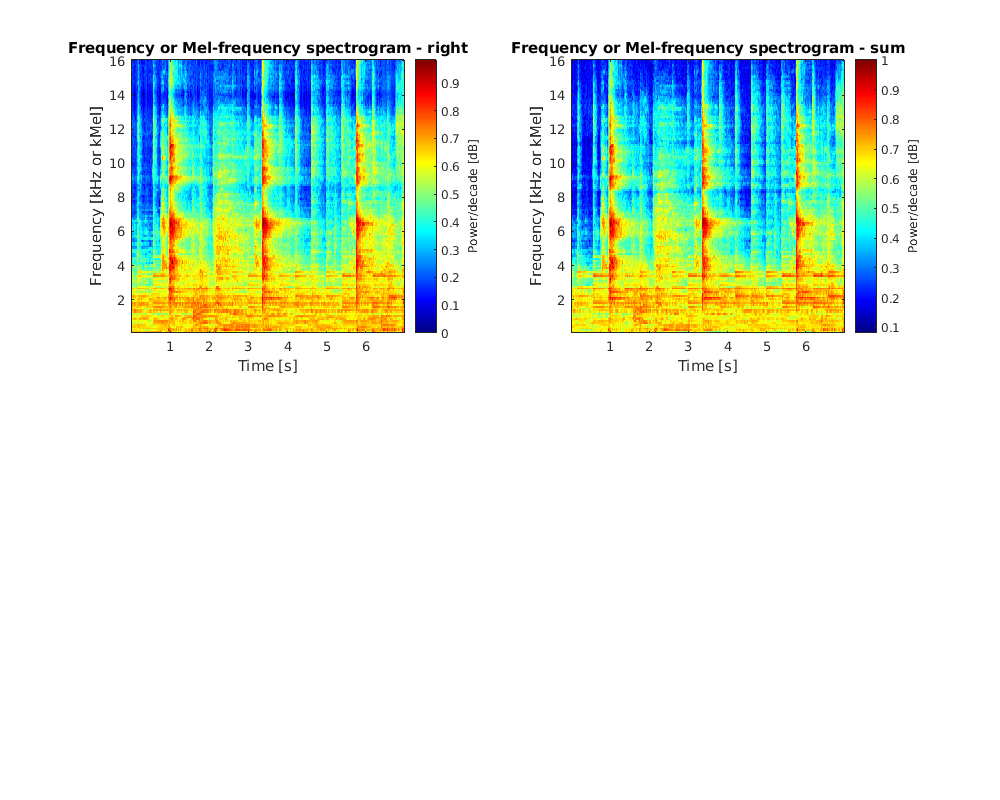

firstFilename = previewAudioFilenames{1};
[stereoSignal, sampleRate] = audioread(fullfile(audioBaseDirs{1}, firstFilename));
[timeValues, freqValues, specgrams] = createSetOfSpecgrams(stereoSignal, sParams);
specgrams = specgrams(:, :, [1 2]);
specgrams = normalizeSpecgrams(specgrams);

specNames = {'right', 'sum', 'difference'};
figure('Position', [0 0 1000 800])

for ii = 1:2
    subplot(2, 2, ii);
    imagesc(timeValues, freqValues / 1000, specgrams(:, :, ii)'); 
    colormap jet; 
    axis xy;  
    pbaspect([1 1 1])
    title(['Frequency or Mel-frequency spectrogram - ', specNames{ii}])
    xlabel('Time [s]')
    ylabel('Frequency [kHz or kMel]')
    ylabel(colorbar, 'Power/decade [dB]')
end

## Save the timeline axis and frequency axis


if exist(outputFilename, 'file') == 2
    delete(outputFilename);
end

h5create(outputFilename, '/axis/time', size(timeValues));
h5create(outputFilename, '/axis/freq', size(freqValues));
h5write(outputFilename, '/axis/time', timeValues);
h5write(outputFilename, '/axis/freq', freqValues);

## Generate spectrograms

specgramSetSize = [sParams.nTimeFrames, sParams.nChannels, ...
    sParams.nSpecgrams];

nAllAudioFilenames = zeros(1, length(audioBaseDirs));
for iAudioBaseDir = 1:length(audioBaseDirs)
    audioFilenames = dir(fullfile(audioBaseDirs{iAudioBaseDir}, '*.wav'));
    nAllAudioFilenames(iAudioBaseDir) = length(audioFilenames);
end

Set datasets paths

baseDsName = '/';
dataDsName = strjoin({baseDsName, 'data'}, '/');
labelsDsName = strjoin({baseDsName, 'labels'}, '/');
filenamesDsName = strjoin({baseDsName, 'filenames'}, '/');

Create a H5 file & datasets    

h5create(outputFilename, dataDsName, [specgramSetSize, sum(nAllAudioFilenames)], ...
    'Chunksize', [specgramSetSize, 1]);
h5create(outputFilename, labelsDsName, sum(nAllAudioFilenames), ...
    'Chunksize', 1);
h5create(outputFilename, filenamesDsName, sum(nAllAudioFilenames), ...
    'ChunkSize', 1, ...
    'Datatype', 'string');

for iAudioBaseDir = 1:length(audioBaseDirs)
    tic
    nAudioFilenames = nAllAudioFilenames(iAudioBaseDir);
    baseDirOffset = sum(nAllAudioFilenames(1:iAudioBaseDir-1));

audioBaseDir = '/ramdisk2/Train/'

Data = 1×16576 string array
  Columns 1 through 399

    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClass

audioBaseDir = '/ramdisk2/Test/'

Data = 1×5920 string array
  Columns 1 through 399

    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceF

Get audio filenames

    audioBaseDir = audioBaseDirs{iAudioBaseDir}
    audioFilenames = sort({dir(fullfile(audioBaseDir, '*.wav')).name});

1/17


batchFilenamesStart = 1

batchFilenamesEnd = 1024

2/17


batchFilenamesStart = 1025

batchFilenamesEnd = 2048

3/17


batchFilenamesStart = 2049

batchFilenamesEnd = 3072

4/17


batchFilenamesStart = 3073

batchFilenamesEnd = 4096

5/17


batchFilenamesStart = 4097

batchFilenamesEnd = 5120

6/17


batchFilenamesStart = 5121

batchFilenamesEnd = 6144

7/17


batchFilenamesStart = 6145

batchFilenamesEnd = 7168

8/17


batchFilenamesStart = 7169

batchFilenamesEnd = 8192

9/17


batchFilenamesStart = 8193

batchFilenamesEnd = 9216

10/17


batchFilenamesStart = 9217

batchFilenamesEnd = 10240

11/17


batchFilenamesStart = 10241

batchFilenamesEnd = 11264

12/17


batchFilenamesStart = 11265

batchFilenamesEnd = 12288

13/17


batchFilenamesStart = 12289

batchFilenamesEnd = 13312

14/17


batchFilenamesStart = 13313

batchFilenamesEnd = 14336

15/17


batchFilenamesStart = 14337

batchFilenamesEnd = 15360

16/17


batchFilenamesStart = 15361

batchFilenamesEnd = 16384

17/17


batchFilenamesStart = 16385

batchFilenamesEnd = 16576

1/6


batchFilenamesStart = 1

batchFilenamesEnd = 1024

2/6


batchFilenamesStart = 1025

batchFilenamesEnd = 2048

3/6


batchFilenamesStart = 2049

batchFilenamesEnd = 3072

4/6


batchFilenamesStart = 3073

batchFilenamesEnd = 4096

5/6


batchFilenamesStart = 4097

batchFilenamesEnd = 5120

6/6


batchFilenamesStart = 5121

batchFilenamesEnd = 5920

Save filenames

    h5write(outputFilename, filenamesDsName, audioFilenames, baseDirOffset+1, length(audioFilenames));

Elapsed time is 76.600326 seconds.


Elapsed time is 27.109347 seconds.


Generate spectrograms

    for iBatch = 1:ceil(nAudioFilenames / processBatchSize)
        fprintf('%d/%d\n', iBatch, ceil(nAudioFilenames / processBatchSize));
        
        batchFilenamesStart = (iBatch - 1) * processBatchSize + 1
        batchFilenamesEnd = min(iBatch * processBatchSize, nAudioFilenames)
        batchSize = batchFilenamesEnd - batchFilenamesStart + 1;
        batchFilenames = audioFilenames(batchFilenamesStart:batchFilenamesEnd);
        batchSpecgrams = zeros([specgramSetSize batchSize]);
        batchLabels = zeros(1, batchSize);
        
        parfor iFilename = 1:batchSize

Create and store spectrogram arrays

            filename = batchFilenames{iFilename};
            [stereoSignal, ~] = audioread(fullfile(audioBaseDir, filename));
            [~, ~, specgrams] = createSetOfSpecgrams(stereoSignal, sParams);
            specgrams = specgrams(:, :, [1 2]);
            specgrams = normalizeSpecgrams(specgrams);
            batchSpecgrams(:, :, :, iFilename) = specgrams;    

 Store label

            filenameParts = strsplit(filename, '_');
            if strcmp(filenameParts{end - 1}, 'front')
                batchLabels(iFilename) = 0;
            elseif strcmp(filenameParts{end - 1}, 'back')
                batchLabels(iFilename) = 1;
            else
                error('"%s": Name has an invalid label', filenameParts{end - 1});
            end
        end

Save spectrograms

        h5write(outputFilename, dataDsName, batchSpecgrams, [1 1 1 baseDirOffset+batchFilenamesStart], ...
            [specgramSetSize, batchSize]);   
        h5write(outputFilename, labelsDsName, batchLabels, baseDirOffset+batchFilenamesStart, batchSize);        
    end
    
    toc
end